n = 200;
x = linspace(-1,1,n); 
y = x;
%% Dataset 2
% ind_y = randperm(n);
% y = x(ind_y);
c = ones(n,1)/n;
r = pdf('Normal',x,0,1)'; r = r/sum(r);
X0 = r*c';
C = zeros(n,n);
for i = 1:n
    for j = 1:n
        C(i,j) = (y(i)-x(j))^2;
    end
end
C = C/max(max(C));


## Other datasets

% n = 1000;
%% Dataset 3
% data = dlmread('map_0.log');
% X = rand(2,n)*2*pi-pi;
% colpicked = randsample(1:40000,n);
% Y = [data(4,colpicked);data(5,colpicked)]; 
%% Dataset 4
% Sigma = [ 1, 0.5, 0.25; 0.5, 1, 0.5; 0.25, 0.5, 1];
% X = sqrt(Sigma)*rand(3,n);
% Y = (sqrt(Sigma)*rand(3,n))*2 - 1;
%% Dataset 6
% Sigma = [ 1,0; 0,1; 1,1; 1,-1];
% X = Sigma*(rand(2,n)*2*pi);
% Y = Sigma*(rand(2,n)*2-1);
%% Dataset 7
% d = 10;
% X = ones(d,1)*rand(1,n)*2*pi;
% Y = (1:d)'*(rand(1,n)*2-1) + ones(d,n);
%% Dataset 8
% X = [0;0;20]*linspace(0,1,n) + (rand(3,n)*0.02 - 0.01);
% t = rand(1,n)*8*pi;
% y1 = sin(t);
% y2 = cos(t);
% Y = [y1;y2;t];
% C = zeros(n,n);
% for i = 1:n
%     for j = 1:n
%         C(i,j) = norm(Y(:,i)-X(:,j))^2;
%     end
% end
% r = ones(n,1)/n;
% c = ones(n,1)/n;
% X0 = r*c';
% C = C/max(max(C));

## Optimal solution

f = reshape(C,[n^2,1]);
row = [repmat((1:n)',[n,1]);kron((n+1:2*n)',ones(n,1))];
col = [1:n^2,1:n^2]';
A = sparse(row,col,ones(2*n^2,1),2*n,n^2);
x_vec = reshape(X0,[n^2,1]);
lb = -x_vec;
tic
options = optimoptions('linprog','Algorithm','dual-simplex','ConstraintTolerance',1e-9,'OptimalityTolerance',1e-10);
[d,val,exitflag,output] = linprog(f,[],[],A,zeros(2*n,1),lb,[],options);

Optimal solution found.



time_global = toc;
x_vec = x_vec + d;
x_opt = x_vec;
X_opt = reshape(x_vec, [n,n]);
f_opt = trace(C'*X_opt);

## Sinkhorn

epsilon = [0.0001,0.001,0.01,0.1];
maxiter = 300000;
time_sink = zeros(maxiter/100 + 1,4);
feas_sink = zeros(maxiter/100 + 1,4);
fval_sink = zeros(maxiter/100 + 1,4);
for num = 1:4
    if num == 1
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X1_sink] = SKstab(r,c,epsilon(num),C,f_opt,maxiter);
    elseif num == 2
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X2_sink] = SKstab(r,c,epsilon(num),C,f_opt,maxiter);
    elseif num == 3
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X3_sink] = SKstab(r,c,epsilon(num),C,f_opt,maxiter); 
    else 
        [iter,time_sink(:,num),feas_sink(:,num),fval_sink(:,num),X1,X4_sink] = SKstab(r,c,epsilon(num),C,f_opt,maxiter);
    end
end

k = 1000, accuracy = 0.010462
k = 2000, accuracy = 0.0098529
k = 3000, accuracy = 0.0084641
k = 4000, accuracy = 0.0077457
k = 5000, accuracy = 0.0071268
k = 6000, accuracy = 0.0060751
k = 7000, accuracy = 0.0057499
k = 8000, accuracy = 0.0053489
k = 9000, accuracy = 0.0046211
k = 10000, accuracy = 0.0040627


k = 1000, accuracy = 0.0042683
k = 2000, accuracy = 0.0016407
k = 3000, accuracy = 0.00064246
k = 4000, accuracy = 0.00025913
k = 5000, accuracy = 0.00011168
k = 6000, accuracy = 5.4942e-05
k = 7000, accuracy = 3.3107e-05
k = 8000, accuracy = 2.4703e-05
k = 9000, accuracy = 2.1469e-05
k = 10000, accuracy = 2.0224e-05


k = 1000, accuracy = 0.00022957
k = 2000, accuracy = 0.00022879
k = 3000, accuracy = 0.00022879
k = 4000, accuracy = 0.00022879
k = 5000, accuracy = 0.00022879
k = 6000, accuracy = 0.00022879
k = 7000, accuracy = 0.00022879
k = 8000, accuracy = 0.00022879
k = 9000, accuracy = 0.00022879
k = 10000, accuracy = 0.00022879


k = 1000, accuracy = 0.0022555
k = 2000, accuracy = 0.0022555
k = 3000, accuracy = 0.0022555
k = 4000, accuracy = 0.0022555
k = 5000, accuracy = 0.0022555
k = 6000, accuracy = 0.0022555
k = 7000, accuracy = 0.0022555
k = 8000, accuracy = 0.0022555
k = 9000, accuracy = 0.0022555
k = 10000, accuracy = 0.0022555


## Accelerated RBCD

maxiter = 10000;
M = 40;
gamma = 0.0001/4/log(n);
Cinf = max(max(C)); 
AA = -C/Cinf/gamma;
X1 = round_matrix(exp(AA),r,c);
[fval_arbcd,time_arbcd,feas_arbcd,X2,card_arbcd]=ARBCD(r,c,n,X1,f_opt,C,M,maxiter,1);

iter = 1000, accuracy = 1.1212e-05
number of successful iterations =972
iter = 1000, accuracy = 9.1153e-06
number of successful iterations =992
iter = 1000, accuracy = 9.7008e-06
number of successful iterations =996
iter = 1000, accuracy = 1.1893e-05
number of successful iterations =985
iter = 1000, accuracy = 5.7965e-06
number of successful iterations =985


## Transportation plan

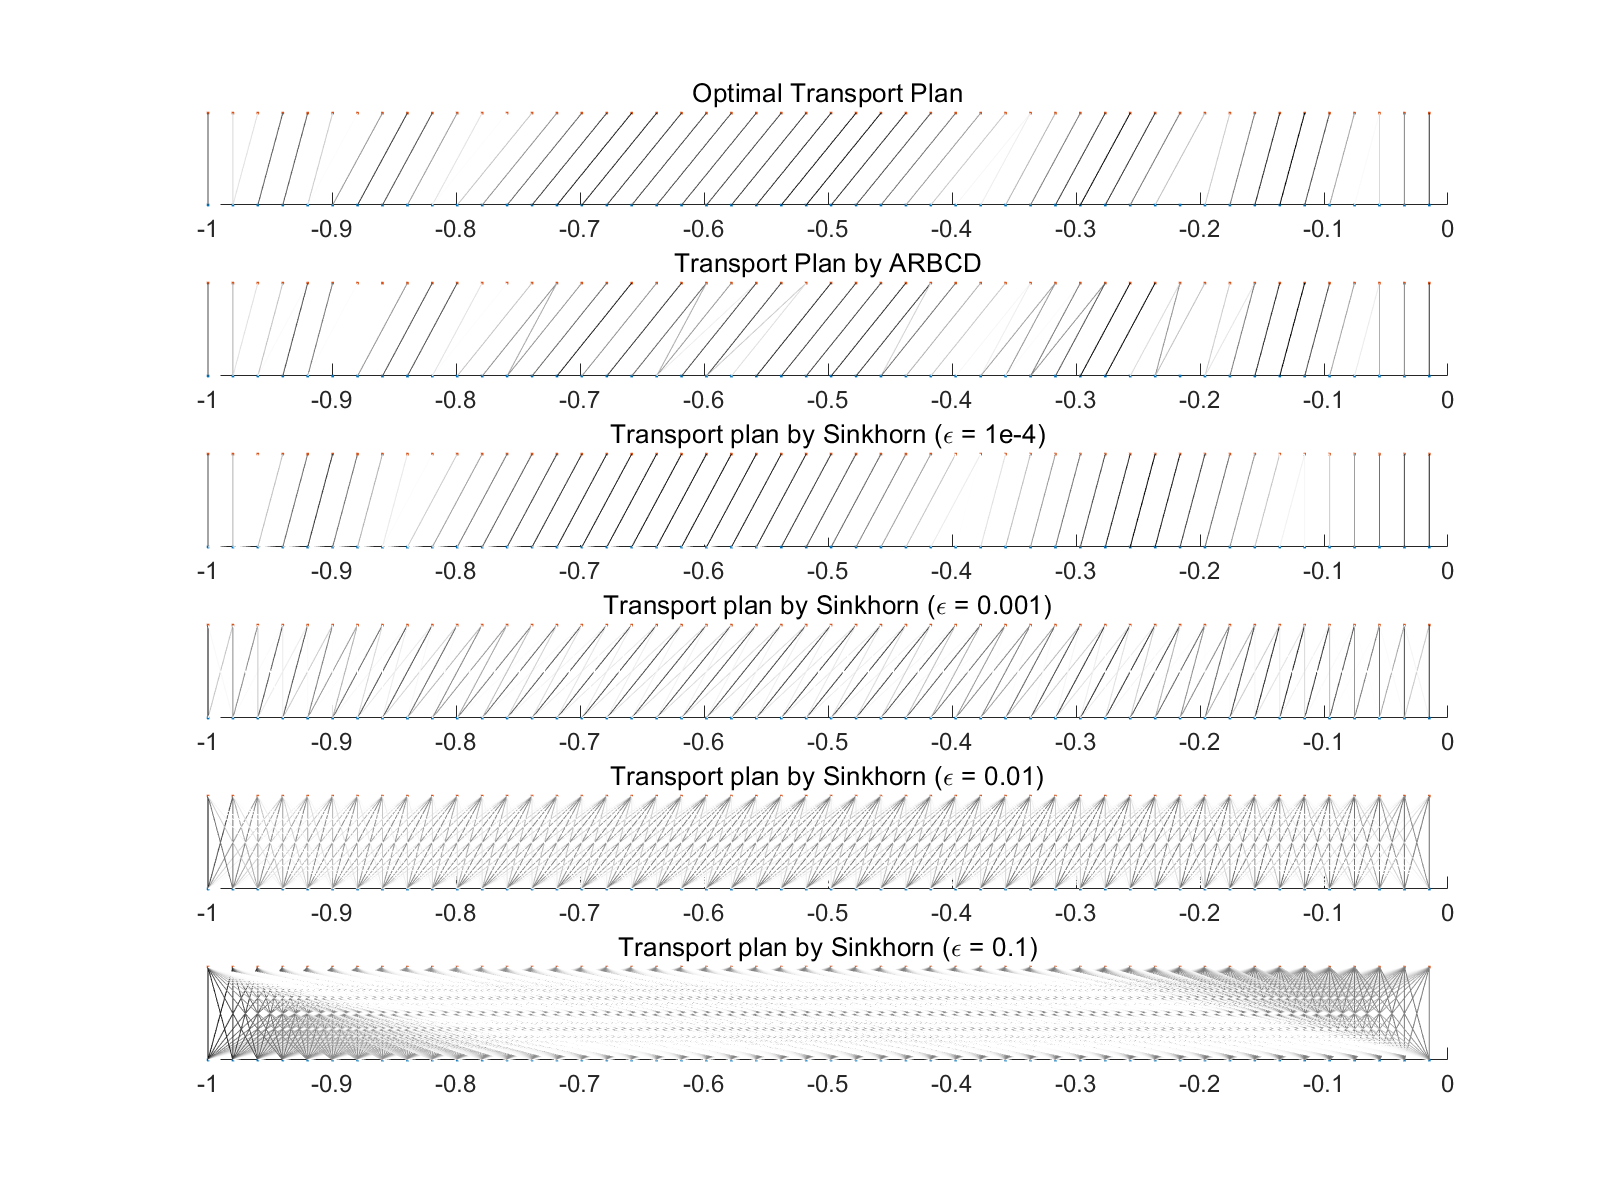

ind = 1:2:99;
l = length(ind);
list = {X_opt,X2,X1_sink,X2_sink,X3_sink,X4_sink};
titlelist = {'Optimal Transport Plan','Transport Plan by ARBCD',... 
    'Transport plan by Sinkhorn (\epsilon = 1e-4)',...
    'Transport plan by Sinkhorn (\epsilon = 0.001)',...
    'Transport plan by Sinkhorn (\epsilon = 0.01)',...
    'Transport plan by Sinkhorn (\epsilon = 0.1)'};
figure()
for k = 1:6
ff=list{k}(ind,ind);
[xx1,xx2]=meshgrid(x(ind),y(ind));
[yy1,yy2]=meshgrid(zeros(1,l),ones(1,l));
xx1=xx1(:);
yy1=yy1(:);
xx2=xx2(:);
yy2=yy2(:);
ff=ff(:);
ff = max(0,ff);
ff = ff/max(ff);
subplot(6,1,k);
scatter(x(ind),zeros(1,l),'.');
hold on
scatter(y(ind),ones(1,l),'.');
set(gca,'YColor',[1 1 1]);
title(titlelist{k})
set(gca,'FontSize',18)
for i = 1:length(xx1)
    if ff(i) > 1e-4
    plot([xx1(i),xx2(i)],[yy1(i),yy2(i)],'Color',[1,1,1]*(1-ff(i)))
    end
end
end
set(gcf,'Innerposition',[200,200,1600,1200])
exportgraphics(gcf,'Transportplans.png','Resolution',500)

## Plot

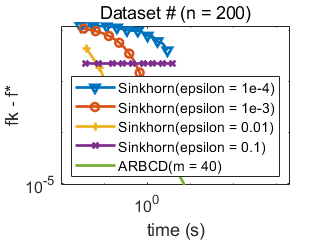

figure
loglog(time_sink(:,1),fval_sink(:,1),'-v','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,2),fval_sink(:,2),'-o','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,3),fval_sink(:,3),'-+','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_sink(:,4),fval_sink(:,4),'-x','MarkerIndices',round(logspace(0,log10(length(fval_sink(:,1))),10)),'LineWidth',2)
hold on
loglog(time_arbcd,fval_arbcd,'LineWidth',2)
xlim([0.01 2e3])
legend('Sinkhorn(epsilon = 1e-4)','Sinkhorn(epsilon = 1e-3)','Sinkhorn(epsilon = 0.01)','Sinkhorn(epsilon = 0.1)',['ARBCD(m = ' ,num2str(M), ')'],'location','southwest')
title(['Dataset # (n = ', num2str(n),')'])
xlabel('time (s)')
ylabel('fk - f*')
set(gca,'FontSize',12)

## IPM

%generate initial subset of nonzero variables
thresh = 1;
while 1
index = distance_index(C,thresh);
if length(index) >= 4*(2*n-1) && length(index) <= 11*(2*n-1)
    break;
else
    thresh = thresh*0.9;
end
end
initialenth = length(index);
%generate input struct
input = struct();
input.m = n;
input.print = false;
input.tol = 1e-10;
input.maxit = 2000;
f = reshape(C,[n^2,1]);
output = OT_IPM([r;c],f,input,index,f_opt);
[f_ipm,ind] = min(output.traj(1:output.iter+1))

f_ipm = 0.0012

ind = 3

feas_ipm = output.feas(ind)

feas_ipm = 2.0669e-17

time_ipm = output.timeall(output.iter+1)

time_ipm = 1.1581

iter_ipm = output.iter

iter_ipm = 20